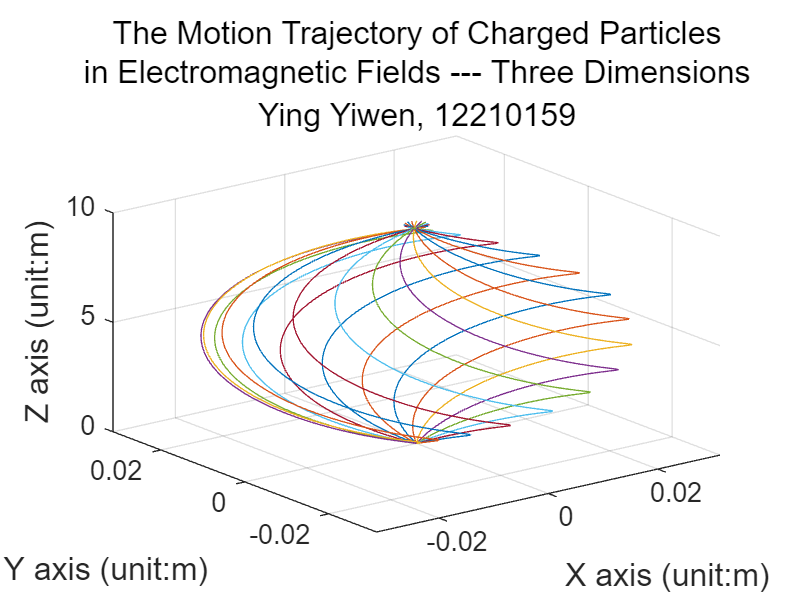

clc;
clear;
close all;

% 实验四：带电粒子在磁场中的聚焦运动
% 姓名：何衍宁
% 学号：12311512

% =========================
% 一、物理参数设置
% =========================
m = 0.02;                    % 粒子质量，单位 kg
q = 1.6e-2;                  % 粒子电荷量，单位 C
E = [0, 0, 0];               % 电场强度矢量，题设中取 0
B = [0, 0, 8];               % 磁通密度矢量，沿 z 轴方向
dt = 0.001;                  % 时间步长，单位 s
t_ends = [1, 3, 8, 20, 100]; % 选取不同观察时长，便于从不同尺度分析轨迹
num_particles = 16;          % 粒子束中粒子个数
output_dir = fullfile(pwd, 'figures'); % 图像输出目录

% 若输出目录不存在，则自动创建
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% =========================
% 二、对不同时间尺度分别作图
% =========================
for case_idx = 1:numel(t_ends)
    t_end = t_ends(case_idx);     % 当前仿真的终止时间
    t = 0:dt:t_end;               % 构造时间数组

    % 创建一张图，内部用三联图显示三维图、俯视图和侧视图
    fig = figure('Color', 'w', 'Position', [100, 100, 1400, 420]);
    tl = tiledlayout(fig, 1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, sprintf('Magnetic Focusing of Charged Particles (t = %g s)\nHe Yanning, 12311512', t_end), ...
        'FontSize', 14, 'FontWeight', 'bold');

    % -------------------------
    % 1. 三维轨迹图
    % -------------------------
    ax1 = nexttile;
    hold(ax1, 'on');
    grid(ax1, 'on');
    view(ax1, 3);
    xlabel(ax1, 'x (m)');
    ylabel(ax1, 'y (m)');
    zlabel(ax1, 'z (m)');
    title(ax1, '3D Trajectories');

    % -------------------------
    % 2. 俯视图（x-y 平面）
    % -------------------------
    ax2 = nexttile;
    hold(ax2, 'on');
    grid(ax2, 'on');
    axis(ax2, 'equal');
    xlabel(ax2, 'x (m)');

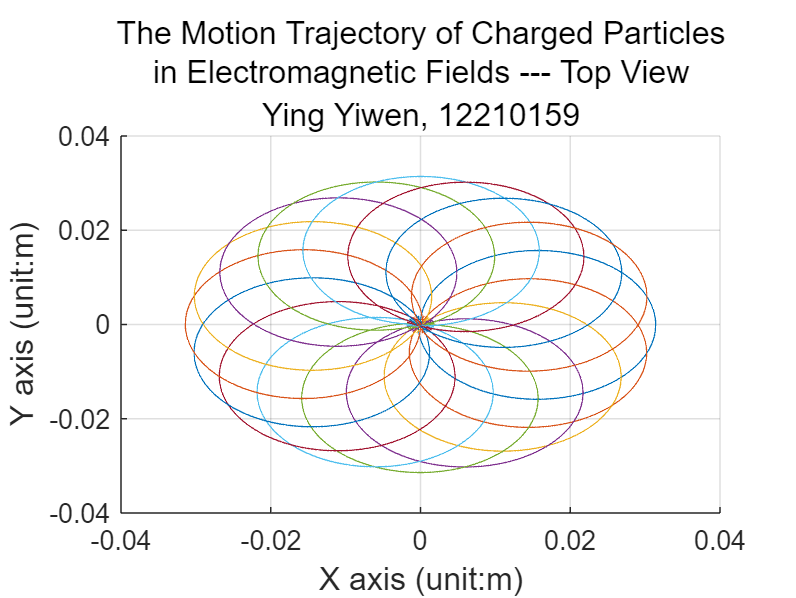

    ylabel(ax2, 'y (m)');
    title(ax2, 'Top View (x-y)');

    % -------------------------
    % 3. 侧视图（x-z 平面）
    % -------------------------
    ax3 = nexttile;
    hold(ax3, 'on');
    grid(ax3, 'on');
    xlabel(ax3, 'x (m)');
    ylabel(ax3, 'z (m)');
    title(ax3, 'Front View (x-z)');

    % 配色方案：为 16 个粒子分配不同颜色，便于区分轨迹
    cmap = lines(num_particles);

    % =========================
    % 三、逐粒子计算运动轨迹
    % =========================
    for k = 0:(num_particles - 1)
        % 设置第 k 个粒子的初速度
        % z 方向分量相同，x-y 平面分量按题目给定的正弦余弦方式分布
        v0 = [0.1 * sin(k * pi / 8), 0.1 * cos(k * pi / 8), 10];

        % 调用子函数，用欧拉法计算粒子轨迹
        [r, v] = simulate_particle(m, q, E, B, dt, t, v0);

        % 在三维图、俯视图和侧视图中分别绘制轨迹
        plot3(ax1, r(:, 1), r(:, 2), r(:, 3), 'Color', cmap(k + 1, :), 'LineWidth', 1.1);
        plot(ax2, r(:, 1), r(:, 2), 'Color', cmap(k + 1, :), 'LineWidth', 1.1);
        plot(ax3, r(:, 1), r(:, 3), 'Color', cmap(k + 1, :), 'LineWidth', 1.1);

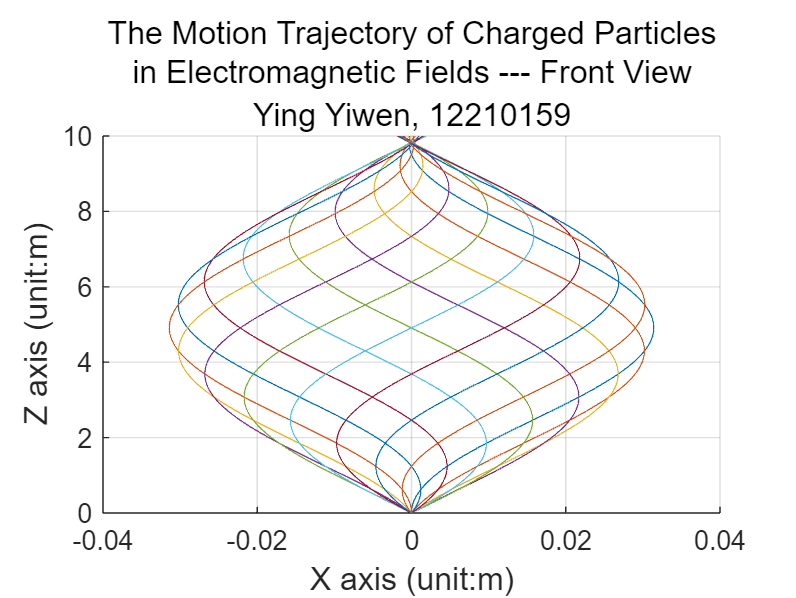


        % 记录第一条轨迹的末速度和末半径，便于在图下方添加说明
        if k == 0
            final_speed = norm(v(end, :));
            final_radius = hypot(r(end, 1), r(end, 2));
        end
    end

    % 图下方附加简短说明，展示参数与计算结果
    annotation(fig, 'textbox', [0.34, 0.01, 0.32, 0.07], ...
        'String', sprintf('m = %.3f kg, q = %.4f C, |B| = %.1f T, dt = %.4f s, sample final speed = %.4f m/s, sample final radius = %.4f m', ...
        m, q, norm(B), dt, final_speed, final_radius), ...
        'HorizontalAlignment', 'center', 'EdgeColor', 'none', 'FontSize', 10);

    % 将当前图保存到 figures 文件夹中
    exportgraphics(fig, fullfile(output_dir, sprintf('magnetic_focusing_t%g.png', t_end)), 'Resolution', 220);
    close(fig);
end

fprintf('Finished generating figures in %s\n', output_dir);

% =========================
% 子函数：用显式欧拉法求解单个粒子的运动过程
% 输入：
%   m, q : 粒子质量和电荷量
%   E, B : 电场和磁场矢量
%   dt   : 时间步长
%   t    : 时间数组
%   v0   : 初速度
% 输出：
%   r    : 每个时刻的位置矢量
%   v    : 每个时刻的速度矢量

% =========================
function [r, v] = simulate_particle(m, q, E, B, dt, t, v0)
num_steps = numel(t);
r = zeros(num_steps, 3);  % 位置数组，三列分别对应 x、y、z
v = zeros(num_steps, 3);  % 速度数组，三列分别对应 x、y、z
v(1, :) = v0;             % 设置初始速度

for i = 1:(num_steps - 1)
    % 计算洛伦兹力：F = qE + q(v × B)
    force = q * E + q * cross(v(i, :), B);

    % 根据牛顿第二定律求加速度：a = F / m
    accel = force / m;

    % 显式欧拉法更新下一时刻速度
    v(i + 1, :) = v(i, :) + accel * dt;

    % 显式欧拉法更新下一时刻位置
    r(i + 1, :) = r(i, :) + v(i, :) * dt;
end
end
